# Problem #4 Graphing Orbit

Here, the orbit of the Halley's comet will be graphed with the sun in the center, along with the orbit of the earth around the sun.

## Set-up

e_halley = 0.9671429; % The eccentricity of Halley's comet-sun orbit
a_halley = 2.667949968 * 10^(12); % Semimajor axis of the Halley's comet-sun orbit [m]
myu_sun = 1.327124400189 * 10^(20); %The standard gravitaional parameter of the 
                                    % sun [m^3/s^2]
e_E = 0.0167; % The eccentricity of the earth-sun orbit 
a_E = 1.49597870700 * 10^(11); % The standard gravitational parameter of the 
                               % earth [m^3/s^2]

## Calculations

In order to plot the elliptical orbit we must figure out two properties: the semimajor axis, "a" and the semiminor axis, "b" of the orbit. Since the semimajor axis is already given and perihelion and aphelion can be expressed using the eccentricity and semimajor axis as


$$r_p \;\;=\;a\left(1-e\right)\;\;\cdots \left(1\right)\;\;\;\;\;\;\;\mathrm{and}\;\;\;\;\;\;\;\;\;\;\;r_a \;\;\;=\;\;a\left(1+e\right)\;\cdots \left(2\right)$$


Now from the mathematic property of the ellipse the realtion between the semimajor axis, the semiminor axis, and the eccentricity is


$$e\;\;=\frac{\sqrt{a^2 -b^2 }}{a}$$
 

maniuplate this and you can obtain 


$$b\;=\sqrt{a^2 \left(1\;-e^2 \right)}$$


and by plugging in (1) and (2) from above


$$b\;=\;\sqrt{r_p \cdot r_a }$$


Then we shall compute the periapsis, apoapsis, and the semiminor axis

% Halley's comet
r_p_halley = a_halley * (1 - e_halley); % Perihelion [m]
r_a_halley = a_halley * (1 + e_halley); % Aphelion [m]
b_halley = sqrt(r_p_halley * r_a_halley); % Semiminor axis [m]

% Earth
r_p_E = a_E * (1 - e_E); % Perigee [m]
r_a_E = a_E * (1 + e_E); % Apogee [m]
b_E = sqrt(r_p_E * r_a_E); % Semiminor axis of earth-sun orbit [m]

## Plotting 

Now that we have all the parameters for plotting the orbit for the Hally's comet and the earth; for both of the orbits the sun is the center of the orbit.

The plot will be done using the parameterization of ellipse equation. In which a general form of a ellipse equation is expressed as 


$$\frac{x^2 }{a^2 }+\frac{y^2 }{b^2 }\;=1\;$$


and when fixed into a parametic equation, in our case using the true anomaly as the parameter. The equations become 


$$x=a\cdot \mathrm{cos}\left(\theta \right)\;\;\;\;\;\;\;\mathrm{and}\;\;\;\;\;\;y=b\cdot \mathrm{sin}\left(\theta \right)\;\;\;$$


For our plot the center (* x = 0, y = 0) is the sun; and therefore the parameterization becomes


$$x\;=a\cdot \mathrm{cos}\left(\theta^* \right)-\sqrt{a^2 -b^2 }\;\;\;\;\;\;\mathrm{and}\;\;\;\;\;\;y\;=b\cdot \mathrm{sin}\left(\theta^* \right)$$


which is in other words


$$x\;=a\cdot \mathrm{cos}\left(\theta^* \right)-\sqrt{a^2 -\left(r_p \cdot r_a \right)}\;\;\;\;\;\mathrm{and}\;\;\;y\;=\sqrt{r_p \cdot r_a }\cdot \mathrm{sin}\left(\theta^* \right)$$


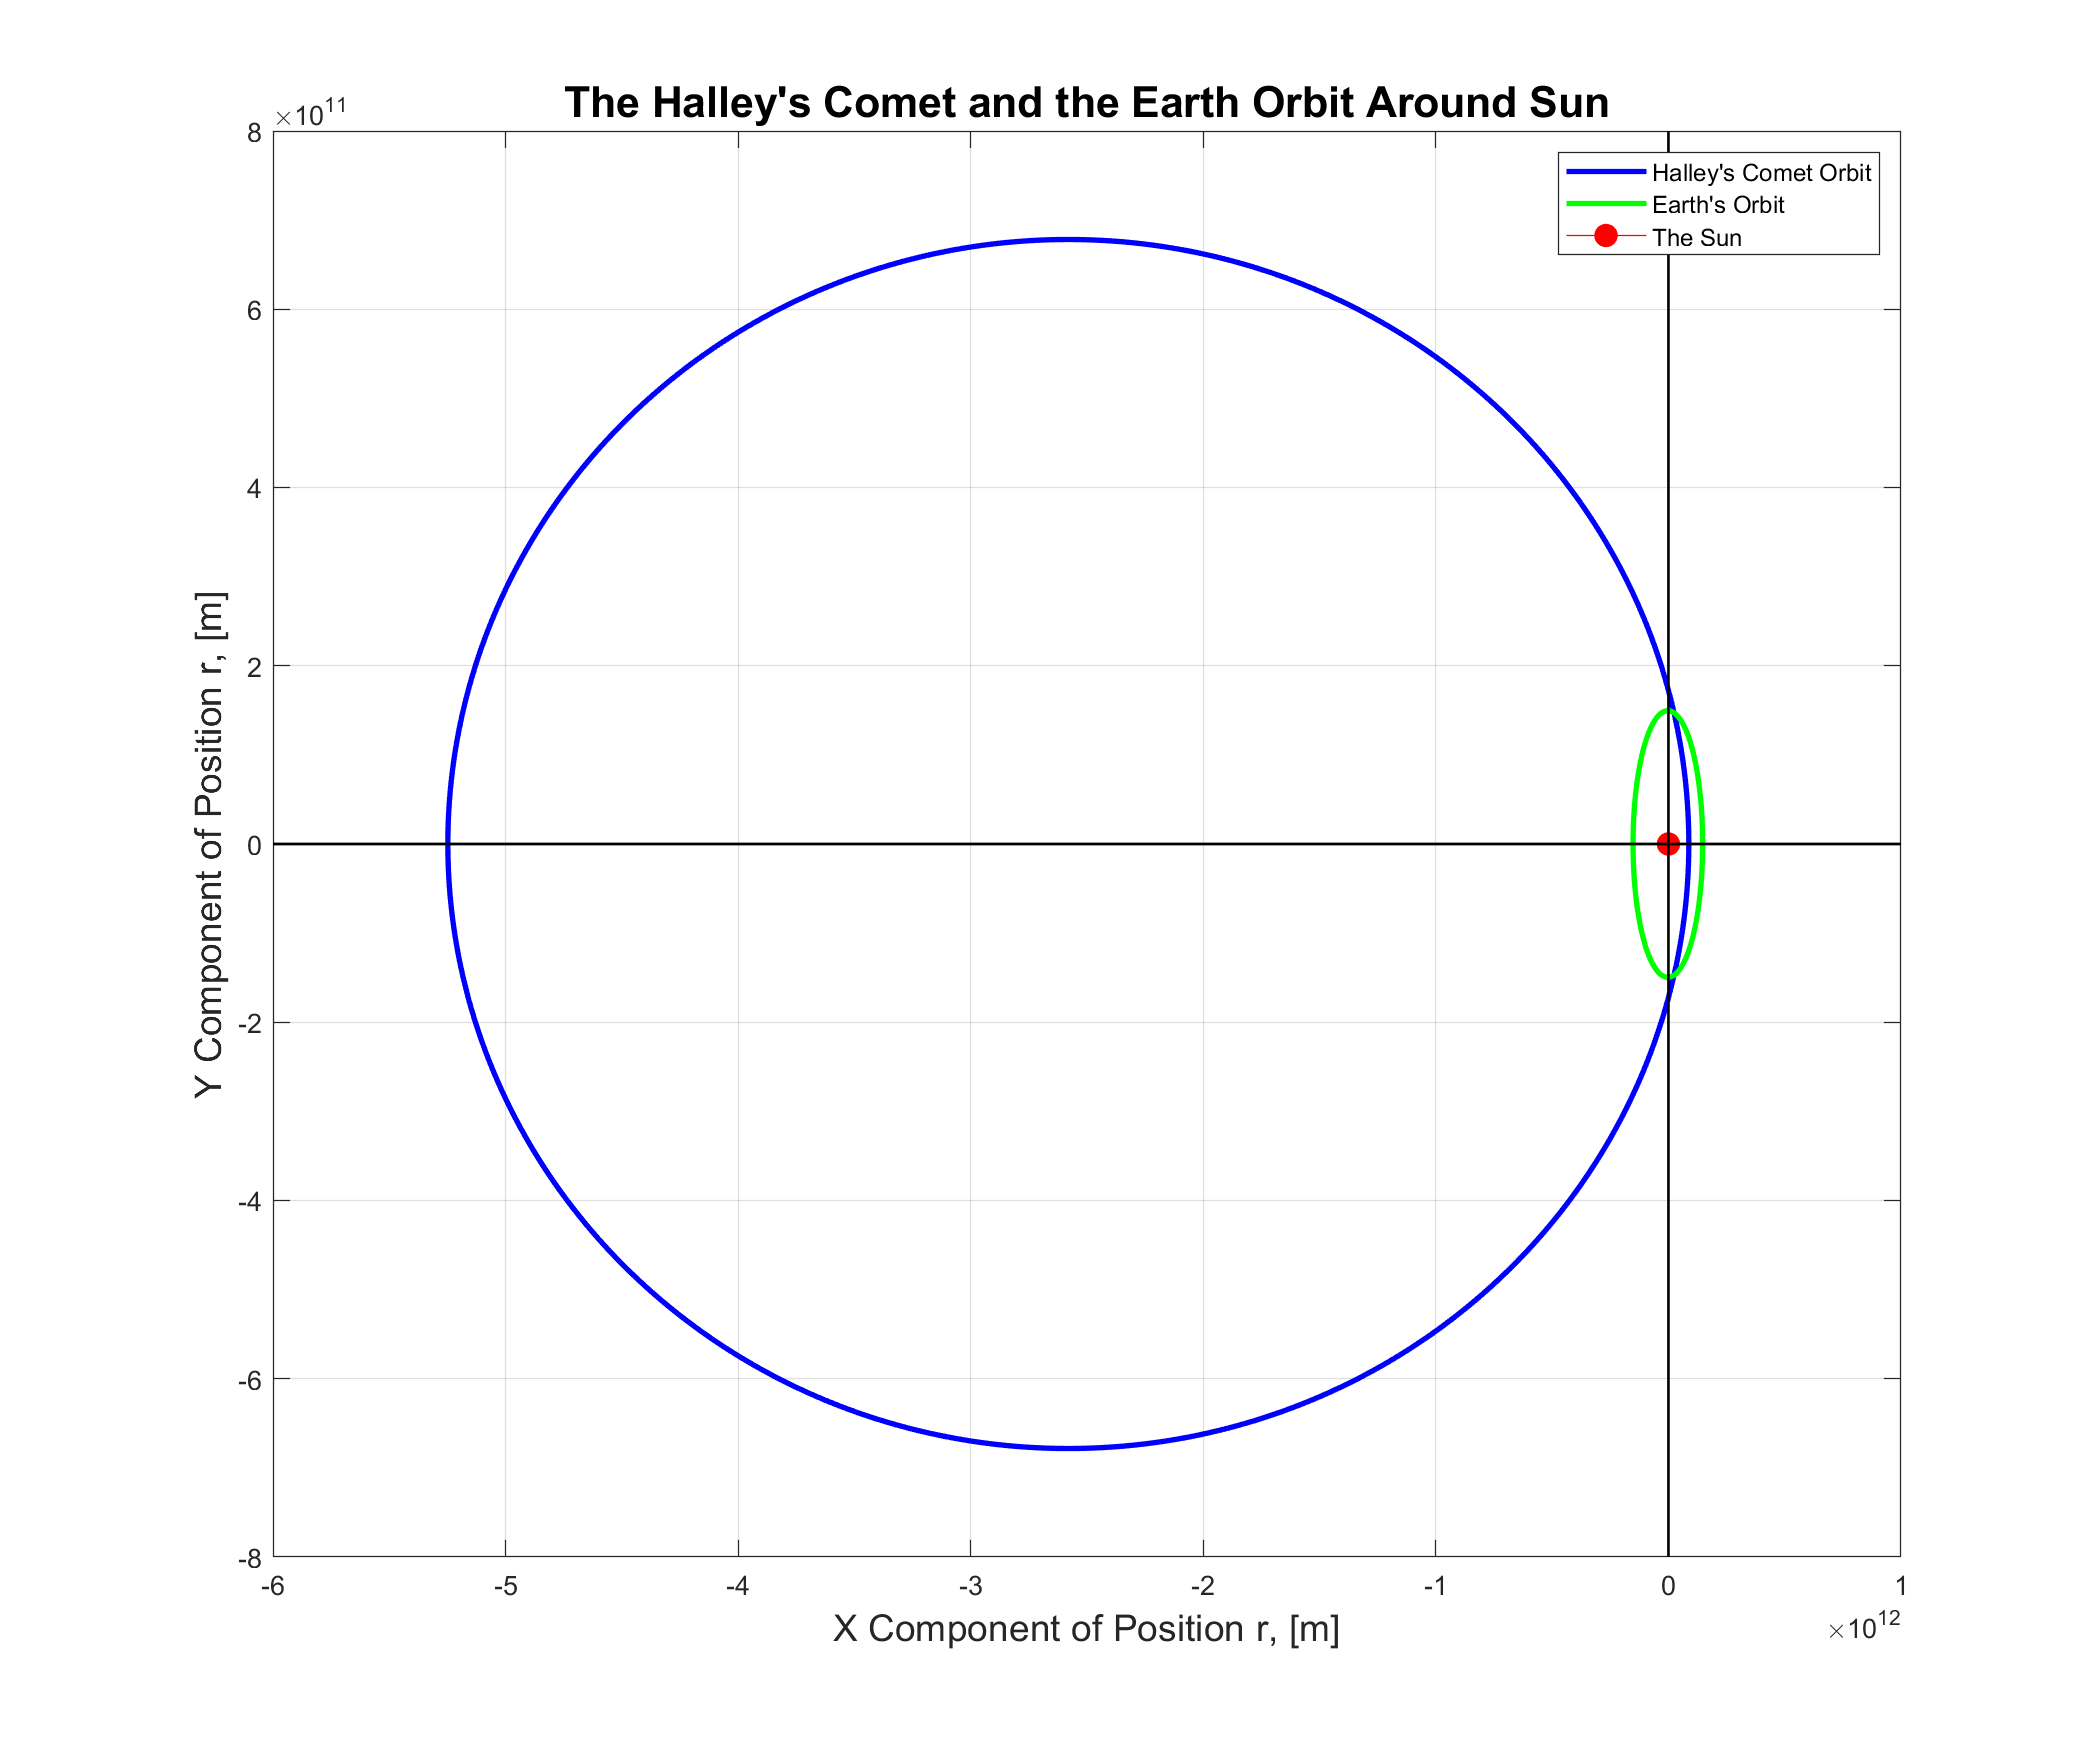

% Adjustments for the plot
linewidth = 2;
fontsize = 14;

% Set-up to plot Halley's comet orbit
theta = 0:360; % The true anomaly ranging from 0 to 360 degrees
x_halley = a_halley * cosd(theta) - sqrt(a_halley^2 - b_halley^2); % X-value parameter
y_halley = b_halley * sind(theta); % Y-value parameter
% Set-up to plot Earth's orbit
x_E = a_E * cosd(theta) - sqrt(a_E^2 - b_E^2); % X-value parameter 
y_E = b_E * sind(theta); % Y-value parameter

% Plotting 
figure(1)
plot(x_halley, y_halley,'Color','b', 'LineStyle','-', 'LineWidth',linewidth);
title('The Halley''s Comet and the Earth Orbit Around Sun', 'FontSize',16)
xlabel('X Component of Position r, [m]', 'FontSize',fontsize)
ylabel('Y Component of Position r, [m]', 'Fontsize', fontsize)
box on
grid on
hold on
plot(x_E, y_E, 'Color', 'g', 'LineStyle','-','LineWidth',linewidth)
plot(0,0,'marker', '.', 'MarkerSize',30, 'color','r') % Plotting the Sun as the center
line([0 0], ylim, 'color', 'k', 'linewidth', 1)
line(xlim, [0 0], 'color', 'k', 'linewidth', 1)
hold off
legend('Halley''s Comet Orbit', 'Earth''s Orbit', 'The Sun', 'Location','northeast')
% Control position of figure
set(gcf,'PaperPositionMode','auto','Position',[0 0 1050 875]) 

## Analysis:

Is there a chance of Halley's comet passing by the earth?

Yes there is most likely a chance of such event occurring. The figure plotted by matlab does not consider the inclination between the orbital planes so is not precisely accurate; however, even having the inclination from the graph we can tell that the two orbits have an instance where the comet and earth approach each other. 

The last time that Halley's comet entered the inner solar system was 1986, and is estimated to return in mid-2061.